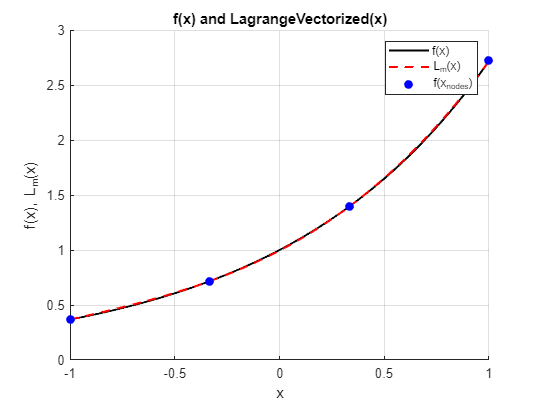

x = linspace(-1, 1, 4);         % nodes
fx = exp(x);                    % f(x) = e^x at nodes
xi = linspace(-1, 1, 1000);     % evaluation points

Lm = LagrangeVectorized(xi, x, fx);

figure;
hold on;

plot(xi, exp(xi), 'k', 'LineWidth', 1.5);
plot(xi, Lm, 'r--', 'LineWidth', 1.5);
plot(x, fx, 'bo', 'MarkerFaceColor', 'b');
legend('f(x)', 'L_m(x)', 'f(x_{nodes})');
xlabel('x'); ylabel('f(x), L_m(x)');
title('f(x) and LagrangeVectorized(x)');
grid on;

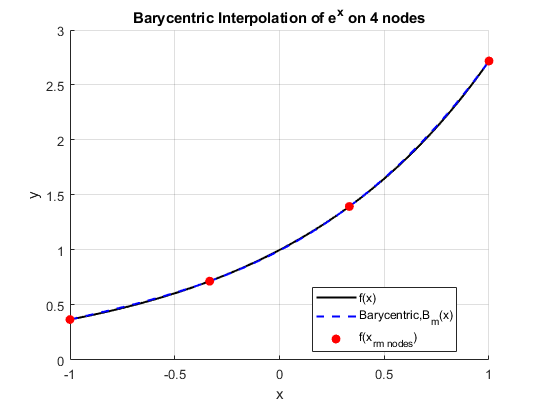


n = numel(x);
c = arrayfun(@(k) 1/ prod( x(k) - x([1:k-1, k+1:n]) ), 1:n );

Bm = BarycentricInterpVectorized(xi, x, fx, c);
figure; hold on;
plot(xi, exp(xi),   'k',  'LineWidth', 1.5);    % exact
plot(xi, Bm,        'b--','LineWidth', 1.5);    % barycentric interp
plot(x,  fx,        'ro', 'MarkerFaceColor', 'r');
legend('f(x)','Barycentric,B_m(x)','f(x_{rm nodes})','Location','best');
xlabel('x'); ylabel('y');
title('Barycentric Interpolation of e^x on 4 nodes');
grid on;